clear 
close all
%% Load Dataset
imageFolder = 'V:\Datasets\Playing Cards\Card Ranks';

imds = imageDatastore(imageFolder, 'LabelSource', 'foldernames',...
    'IncludeSubfolders',true);

img = readimage(imds,1);
imageSize = size(img);

labelCount = countEachLabel(imds)

labelCount = 13×2 table
    Label    Count
    _____    _____

      1      1016 
      2      1016 
      3      1016 
      4      1016 
      5      1016 
      6      1016 
      7      1016 
      8      1016 
      9      1016 
      A      1016 
      J      1016 
      K      1016 
      Q      1016 



augmenter = imageDataAugmenter( ...
    'RandRotation',[0 360], ...
    'RandScale',[0.5 1])

augmenter =   imageDataAugmenter with properties:

           FillValue: 0
     RandXReflection: 0
     RandYReflection: 0
        RandRotation: [0 360]
           RandScale: [0.5000 1]
          RandXScale: [1 1]
          RandYScale: [1 1]
          RandXShear: [0 0]
          RandYShear: [0 0]
    RandXTranslation: [0 0]
    RandYTranslation: [0 0]



[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomize');


augTrain =   augmentedImageDatastore with properties:

             NumObservations: 9243
                       Files: {9243×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: [1×1 imageDataAugmenter]
          ColorPreprocessing: 'none'
                  OutputSize: [128 128]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


augVal =   augmentedImageDatastore with properties:

             NumObservations: 3965
                       Files: {3965×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: [1×1 imageDataAugmenter]
          ColorPreprocessing: 'none'
                  OutputSize: [128 128]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


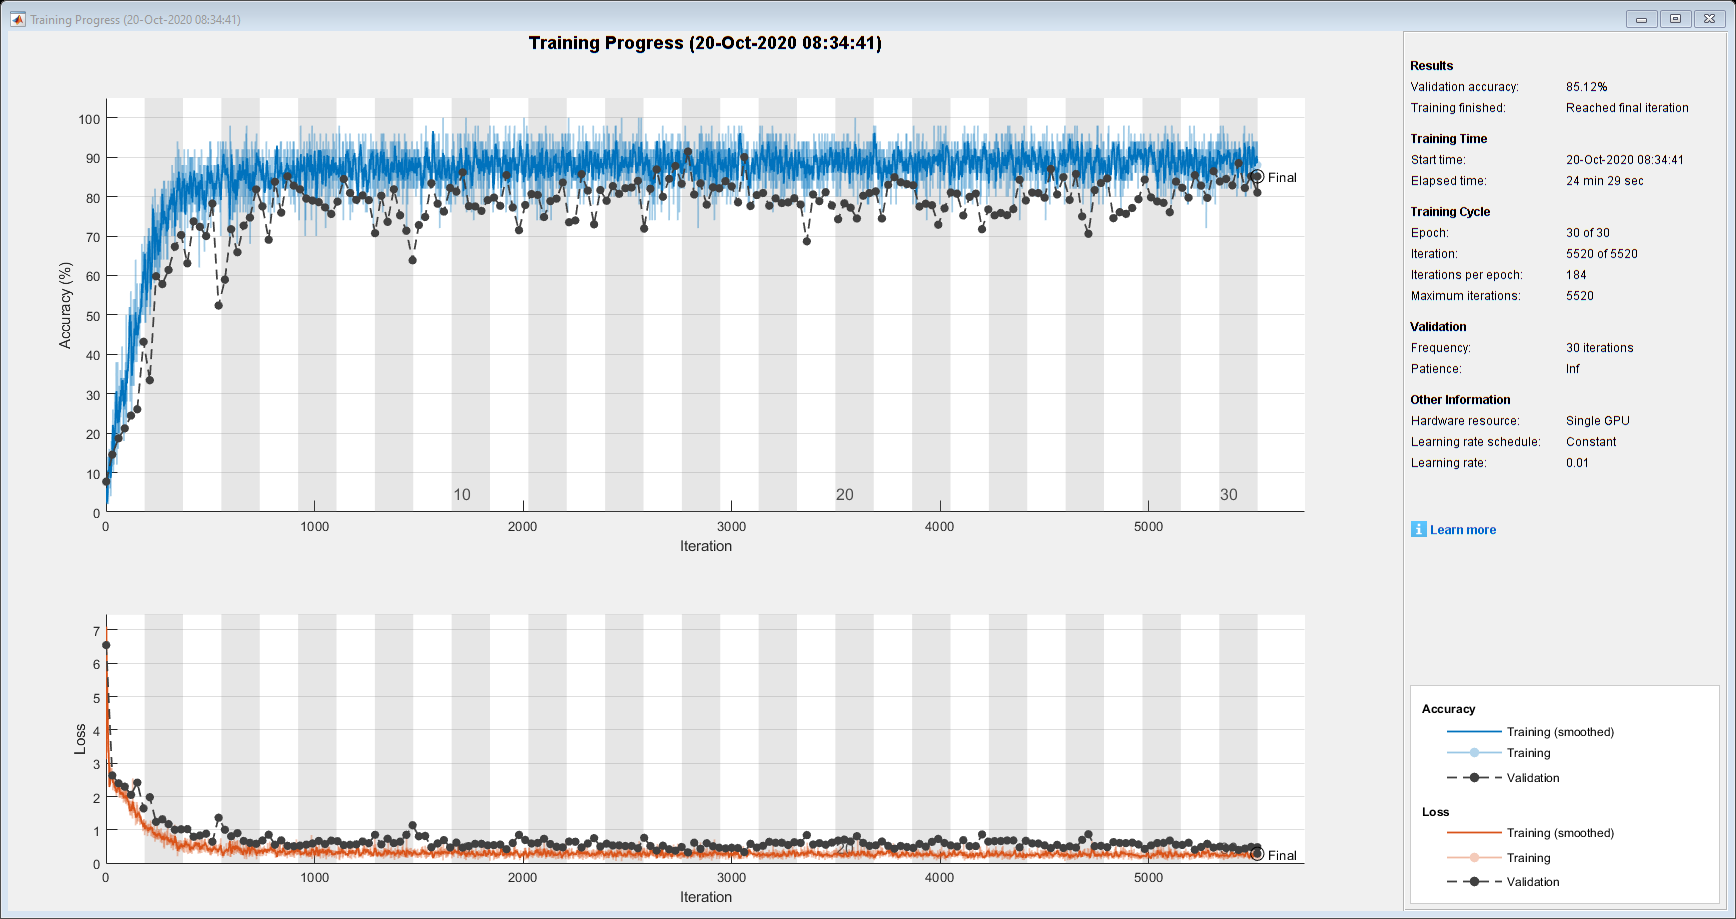

augTrain = augmentedImageDatastore(imageSize,imdsTrain,'DataAugmentation',augmenter)
augVal = augmentedImageDatastore(imageSize,imdsValidation,'DataAugmentation',augmenter)

layers = [
    imageInputLayer([128 128 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(13)
    softmaxLayer
    classificationLayer];

options = trainingOptions('adam', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',30, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'MiniBatchSize',50,...
    'Plots','training-progress');

net = trainNetwork(augTrain,layers,options);


YPred = classify(net,augVal);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9004


save ranksClassifierCNN3
